% Color Opponent Model - Clean  and commented version for GitHub
% Created September 21st, 2022
% Last Edited September 29st, 2022
% Author: Dragos Rezeanu, Neitz Lab, University of Washington
% Contact information: drezeanu@uw.edu

clear
close all
format short g

## Load Core Variables

% Wavelength variables every 5, 1, and 0.1 nm

WL_5 = 400:5:700;
WL_1 = 400:1:700;
WL_01 = 400:0.1:700;

% Import CIE tristimulus values, D65 spectrum, and D50 spectrum

CIEtristimulus = readmatrix("CIE Standards.xlsx", "Sheet", "Tristimulus Values", "Range", "B3:D303");
CIEtristimulus_01 = interp1(WL_1, CIEtristimulus, WL_01, 'spline');
CIEuv = readmatrix("CIE Standards.xlsx", "Sheet", "Tristimulus Values", "Range", "G3:H303");
CIEuv = interp1(WL_1, CIEuv, WL_01, 'spline');
CIExy = readmatrix("CIE Standards.xlsx", "Sheet", "Tristimulus Values", "Range", "E3:F303");
CIExy = interp1(WL_1, CIExy, WL_01, 'spline');
d65spectrum = readmatrix("CIE Standards.xlsx", "Sheet", "Standard Illuminants", "Range", "C2:C302");
d50spectrum = readmatrix("CIE Standards.xlsx", "Sheet", "Standard Illuminants", "Range", "B2:B302");
d65spectrum = d65spectrum./max(d65spectrum);
d50spectrum = d50spectrum./max(d50spectrum);

% Set LMS cone spectral peaks and optical densities

conePeaks = [419, 530, 557.25];
coneOD = [0.4, 0.22, 0.34];

% Set stimulus size

stimSize = 2; % stim diameter in degrees of visual angle
eccentricityAtStim = stimSize/2;

% Set L:M Ratio

LM_Ratio = [2,1];
percent_L = LM_Ratio(1)/sum(LM_Ratio);
percent_M = 1-percent_L;

% Estimate macular pigment density (as percent of max) for chosen stimulus size

eccentricity = linspace(-9,9,73);
mpDensity = [0,0,0.5,1,0.5,0,0];
roughEcc = [-9,-5,-1,0,1,5,9];

mpDensity_int = interp1(roughEcc, mpDensity, eccentricity, 'pchip');

percentMp = mpDensity_int(eccentricity==eccentricityAtStim); % percent of maximum MP at given eccentricity

% Override for setting macular pigment percentage manually

manualMP = false;

if manualMP == true
    percentMp = 0.5;
end

% Derive cone spectral sensitivities and convert from quanta to energy

energyConversion = WL_5./WL_5(end);

s_cone = spec(conePeaks(1), coneOD(1), 0, percentMp);
m_cone = spec(conePeaks(2), coneOD(2), 0, percentMp);
l_cone = spec(conePeaks(3), coneOD(3), 0, percentMp);

s_cone = s_cone.*energyConversion;
m_cone = m_cone.*energyConversion;
l_cone = l_cone.*energyConversion;

s_cone = s_cone./max(l_cone);
m_cone = m_cone./max(l_cone);
l_cone = l_cone./max(l_cone);

s_cone_1 = interp1(WL_5, s_cone, WL_1, 'spline');
m_cone_1 = interp1(WL_5, m_cone, WL_1, 'spline');
l_cone_1 = interp1(WL_5, l_cone, WL_1, 'spline');

s_cone_01 = interp1(WL_5, s_cone, WL_01, 'spline');
m_cone_01 = interp1(WL_5, m_cone, WL_01, 'spline');
l_cone_01 = interp1(WL_5, l_cone, WL_01, 'spline');

surround = percent_L*l_cone + percent_M*m_cone;
surround_1 = interp1(WL_5, surround, WL_1, 'spline');
surround_01 = interp1(WL_5, surround, WL_01, 'spline');

## Plot cone spectral sensitivities and macular pigment 

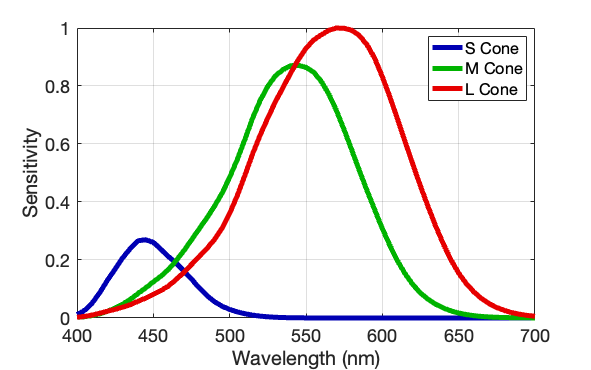

fundamentals = figure;
fundamentals.Position = [1080, 1080, 1080, 1080*10/16];

plot(WL_5, s_cone, '-', 'Color', [0,0,0.7],'LineWidth', 5);
hold on
grid on
plot(WL_5, m_cone, '-', 'Color', [0, 0.7, 0], 'LineWidth', 5);
plot(WL_5, l_cone, '-', 'Color', [0.9, 0, 0], 'LineWidth', 5);
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
ylim([0,1])
legend({'S Cone', 'M Cone', 'L Cone'}, 'Location', 'northeast')
hold off

fundamentals.CurrentAxes.FontSize = 18;

## Calculate Gain Coefficients for Environmental White

options = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt', 'Display', 'off');

x0 = [1,1];

% Set environmental white
useD65 = false; useD50=false;

% Derive von Kries coefficients for cone-opponent mechanisms

if  useD65 == true
    disp('Environment = D65 white')
    gainsLLM = lsqnonlin(@(x)sum((l_cone_1.*x(1) - surround_1.*x(2)).*d65spectrum), x0, [], [], options);
    gainsMLM = lsqnonlin(@(x)sum((m_cone_1.*x(1) - surround_1.*x(2)).*d65spectrum), x0, [], [], options);
    gainsSLM = lsqnonlin(@(x)sum((s_cone_1.*x(1) - surround_1.*x(2)).*d65spectrum), x0, [], [], options);
    gainsSM = lsqnonlin(@(x) sum((s_cone_1.*x(1) - m_cone_1.*x(2)).*d65spectrum), x0, [], [], options);
    gainsSL = lsqnonlin(@(x) sum((s_cone_1.*x(1) - l_cone_1.*x(2)).*d65spectrum), x0, [], [], options);
elseif useD50 == true
    disp('Environment = D50 white')
    gainsLLM = lsqnonlin(@(x)sum((l_cone_1.*x(1) - surround_1.*x(2)).*d50spectrum), x0, [], [], options);
    gainsMLM = lsqnonlin(@(x)sum((m_cone_1.*x(1) - surround_1.*x(2)).*d50spectrum), x0, [], [], options);
    gainsSLM = lsqnonlin(@(x)sum((s_cone_1.*x(1) - surround_1.*x(2)).*d50spectrum), x0, [], [], options);
    gainsSM = lsqnonlin(@(x) sum((s_cone_1.*x(1) - m_cone_1.*x(2)).*d50spectrum), x0, [], [], options);
    gainsSL = lsqnonlin(@(x) sum((s_cone_1.*x(1) - l_cone_1.*x(2)).*d50spectrum), x0, [], [], options);
else
    disp('Environment = EE White')
    gainsLLM = lsqnonlin(@(x) sum(l_cone_1.*x(1) - surround_1.*x(2)), x0, [], [], options);
    gainsMLM = lsqnonlin(@(x) sum(m_cone_1.*x(1) - surround_1.*x(2)), x0, [], [], options);
    gainsSLM = lsqnonlin(@(x) sum(s_cone_1.*x(1) - surround_1.*x(2)), x0, [], [], options);
    gainsSM = lsqnonlin(@(x) sum(s_cone_1.*x(1) - m_cone_1.*x(2)), x0, [], [], options);
    gainsSL = lsqnonlin(@(x) sum(s_cone_1.*x(1) - l_cone_1.*x(2)), x0, [], [], options);
end

Environment = EE White


## Calculate and Plot Cone and Color Opponent Mechanisms

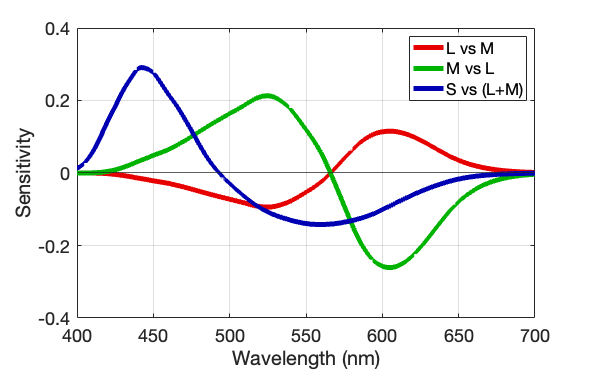

% Calculate and plot cone-opponent mechanisms

LvsM = l_cone_01.*gainsLLM(1) - surround_01.*gainsLLM(2);
MvsL = m_cone_01.*gainsMLM(1) - surround_01.*gainsMLM(2);
SvsLM = s_cone_01.*gainsSLM(1) - surround_01.*gainsSLM(2);
SvsM = s_cone_01.*gainsSM(1) - m_cone_01.*gainsSM(2);
SvsL = s_cone_01.*gainsSL(1) - l_cone_01.*gainsSL(2);

coneopp = figure;
coneopp.Position = [1080, 1080, 1080, 1080*10/16];

plot(WL_01, LvsM, '-', 'Color', [0.9,0,0], 'LineWidth', 5);
hold on
grid on
plot(WL_01, MvsL, '-', 'Color', [0,0.7,0], 'LineWidth', 5);
plot(WL_01, SvsLM, '-', 'Color', [0,0,0.7], 'LineWidth', 5);
yline(0)
ylim([-0.4, 0.4]);
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
legend({'L vs M', 'M vs L', 'S vs (L+M)'}, 'Location', 'northeast')
hold off

coneopp.CurrentAxes.FontSize = 18;

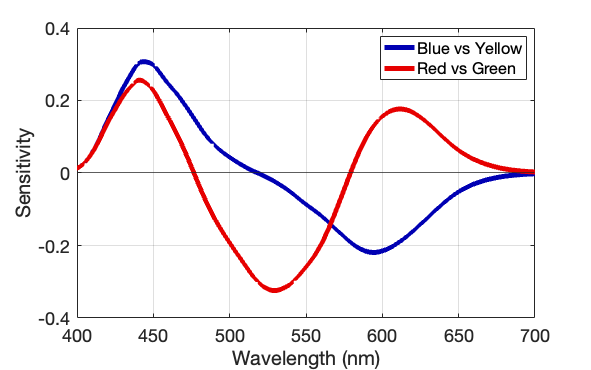


% Calculate and plot color-opponent mechanisms

BY = SvsLM - LvsM;
RG = SvsLM - MvsL;

coloropp = figure;
coloropp.Position = [1080, 1080, 1080, 1080*10/16];

plot(WL_01, BY, '-', 'Color', [0,0,0.7], 'LineWidth', 5);
hold on
grid on
plot(WL_01, RG, '-', 'Color', [0.9,0,0], 'LineWidth', 5);
yline(0)
ylim([-0.4, 0.4])
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
legend({'Blue vs Yellow', 'Red vs Green'}, "Location", 'northeast')
hold off

coloropp.CurrentAxes.FontSize = 18;

## Calculate Unique Hues

threshold = 0.0006;

BY_crossings = WL_01(BY > 0-threshold & BY < 0+threshold);
RG_crossings = WL_01(RG > 0-threshold & RG < 0+threshold);
BY_crossings = BY_crossings(BY_crossings < 600);
RG_crossings = RG_crossings(RG_crossings<699);
Deutan_crossings = WL_01(SvsL > 0-threshold & SvsL < 0+threshold);
Protan_crossings = WL_01(SvsM > 0-threshold & SvsM < 0+threshold);
Deutan_crossings = Deutan_crossings(Deutan_crossings < 600);
Protan_crossings = Protan_crossings(Protan_crossings < 600);

while length(RG_crossings) < 2 && isempty(BY_crossings)
    threshold = threshold+0.0001;
    BY_crossings = WL_01(BY > 0-threshold & BY < 0+threshold);
    RG_crossings = WL_01(RG > 0-threshold & RG < 0+threshold);
    BY_crossings = BY_crossings(BY_crossings < 600);
    RG_crossings = RG_crossings(RG_crossings < 699);
end

uniqueBlue = RG_crossings(1);
uniqueYellow = RG_crossings(end);
uniqueGreen = round(median(BY_crossings),1);
protanGreen = round(median(Protan_crossings),1);
deutanGreen = round(median(Deutan_crossings),1);

disp(['Unique Blue is ', num2str(uniqueBlue), ' nm']);

Unique Blue is 476.6 nm


disp(['Unique Green is ', num2str(uniqueGreen), ' nm']);

Unique Green is 518.3 nm


disp(['Unique Yellow is ', num2str(uniqueYellow), ' nm']);

Unique Yellow is 579.1 nm


disp(['The Protan neutral point is ', num2str(protanGreen), ' nm'])

The Protan neutral point is 488.6 nm


disp(['The Deutan neutral point is ', num2str(deutanGreen), ' nm'])

The Deutan neutral point is 495.4 nm


## Calculate LMS Activation Ratios and Set Weber Fractions

LMSResponses = zeros(length(WL_01),3);
LMSRatios = zeros(length(WL_01), 3);

LMWeberFraction = 0.3;
SWeberFraction = 0.5;

for x=1:length(WL_01)
    LMSResponses(x,:) = [l_cone_01(WL_01==(WL_01(x))), m_cone_01(WL_01==(WL_01(x))), s_cone_01(WL_01==(WL_01(x)))];
    LMSRatios(x,:) = LMSResponses(x,:)./min(LMSResponses(x,1:2));
end


## Plot RG and BY Null Points on CIE xy Chromaticity Diagram

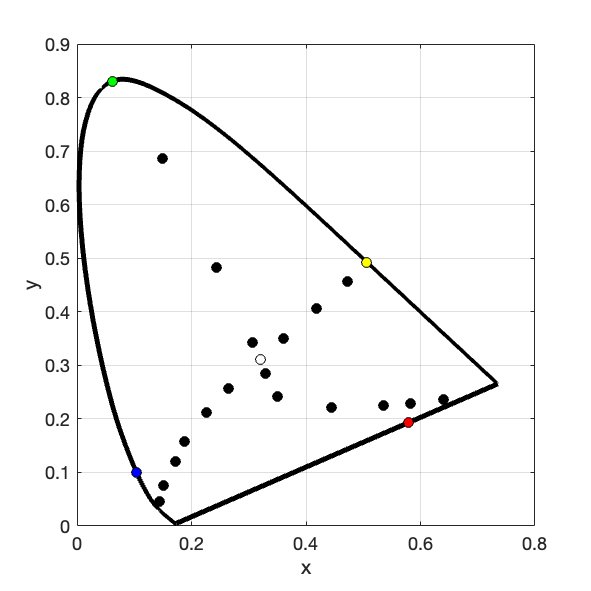

% Derive achromatic point

BYNullPoint = lsqnonlin(@(x) BY(WL_01==uniqueBlue).*x(1)-abs(BY(WL_01==uniqueYellow)).*x(2), x0, [], [], options);

achromatic_XYZ = CIEtristimulus_01(WL_01==uniqueBlue,:).*BYNullPoint(1)+CIEtristimulus_01(WL_01==uniqueYellow,:).*BYNullPoint(2);
achromatic_xy = [achromatic_XYZ(1)./sum(achromatic_XYZ), achromatic_XYZ(2)./sum(achromatic_XYZ)];

% Derive unique red, including adaptation

primaries = [400, 700];

adaptationRatios = LMSRatios(WL_01==primaries(1),:)+LMSRatios(WL_01==primaries(2),:);
adaptationRatios = adaptationRatios./min(adaptationRatios);
adaptationRatios(1:2) = adaptationRatios(1:2)*LMWeberFraction;
adaptationRatios(3) = adaptationRatios(3)*SWeberFraction;

adaptationRatios(adaptationRatios<1) = 1;

L_adapted = l_cone_01.*(1/adaptationRatios(1));
M_adapted = m_cone_01.*(1/adaptationRatios(2));
S_adapted = s_cone_01.*(1/adaptationRatios(3));
surround_adapted = percent_L.*L_adapted + percent_M.*M_adapted;

LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);

BY_adapted = SvsLM_adapted - LvsM_adapted;
RG_adapted = SvsLM_adapted - MvsL_adapted;

redNull = lsqnonlin(@(x) BY_adapted(WL_01==400).*x(1)-abs(BY_adapted(WL_01==700)).*x(2), x0, [], [], options);
red_XYZ = CIEtristimulus_01(WL_01==400,:).*redNull(1)+CIEtristimulus_01(WL_01==700,:).*redNull(2);
red_xy = [red_XYZ(1)./sum(red_XYZ), red_XYZ(2)./sum(red_XYZ)];

% Plot unique hue loci in xy chromaticity space

xyPlot = figure;
xyPlot.Position = [1080, 1080, 1080, 1080];

plot(CIExy(:,1), CIExy(:,2), '-k', 'LineWidth', 5);
grid on
hold on
plot([CIExy(1,1), CIExy(end,1)], [CIExy(1,2), CIExy(end,2)], '-k', 'LineWidth', 5);
ylim([0,0.9])
xlim([0,0.8])
plot(achromatic_xy(1), achromatic_xy(2), 'Marker', 'o', 'MarkerFaceColor', 'w', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
plot(CIExy(WL_01==uniqueBlue,1), CIExy(WL_01==uniqueBlue,2), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
plot(CIExy(WL_01==uniqueYellow,1), CIExy(WL_01==uniqueYellow,2), 'Marker', 'o', 'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
plot(CIExy(WL_01==uniqueGreen, 1), CIExy(WL_01==uniqueGreen, 2), 'Marker', 'o', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
xlabel('x')
ylabel('y')
plot(red_xy(1), red_xy(2), 'Marker', 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)

% Determine Blue Yellow Null Points using a short wavelength light (470)
% and a series of long wavelength lights (530, 550, 570, 580, 590, 610, 640)

shortWavelength = 470;
longWavelengths = [530, 550, 570, 580, 590, 610, 628, 642, 670];

for i = 1:length(longWavelengths)
    adaptationRatios = LMSRatios(WL_01==shortWavelength,:)+LMSRatios(WL_01==longWavelengths(i),:);
    adaptationRatios = (adaptationRatios./min(adaptationRatios)).*LMWeberFraction;
    adaptationRatios(adaptationRatios<1) = 1;
    L_adaptation = 1./adaptationRatios(1);
    M_adaptation = 1./adaptationRatios(2);
    S_adaptation = 1./adaptationRatios(3);
    L_adapted = l_cone_01.*L_adaptation;
    M_adapted = m_cone_01.*M_adaptation;
    S_adapted = s_cone_01.*S_adaptation;
    surround_adapted = percent_L.*L_adapted+percent_M.*M_adapted;
    LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
    MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
    SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);
    BY_adapted = SvsLM_adapted - LvsM_adapted;
    RG_adapted = SvsLM_adapted - MvsL_adapted;
    nullPoint = lsqnonlin(@(x) BY_adapted(WL_01==shortWavelength).*x(1)-abs(BY_adapted(WL_01==longWavelengths(i))).*x(2), x0, [], [], options);
    point_XYZ = CIEtristimulus_01(WL_01==shortWavelength,:).*nullPoint(1)+CIEtristimulus_01(WL_01==longWavelengths(i),:).*nullPoint(2);
    point_xy = [point_XYZ(1)./sum(point_XYZ), point_XYZ(2)./sum(point_XYZ)];
    plot(point_xy(1), point_xy(2), 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
end

% Determine Red/Green Null Points using unique Yellow as a desaturant

desaturationSeries = [0.02, 0.06, 0.13, 0.18, 0.30, 0.45, 1.2, 2.4, 8];
adaptationWavelengths = [440, 445, 447.5, 450, 450, 450, 450, 450, 450];
threshold = 0.0007;

for i = 1:length(desaturationSeries)
    adaptationRatios = LMSRatios(WL_01==adaptationWavelengths(i),:)+LMSRatios(WL_01==uniqueYellow,:).*desaturationSeries(i);
    adaptationRatios = (adaptationRatios./min(adaptationRatios));
    adaptationRatios(1:2) = adaptationRatios(1:2).*LMWeberFraction;
    adaptationRatios(3) = adaptationRatios(3).*SWeberFraction;
    adaptationRatios(adaptationRatios<1)=1;
    L_adaptation = 1./adaptationRatios(1);
    M_adaptation = 1./adaptationRatios(2);
    S_adaptation = 1./adaptationRatios(3);
    L_adapted = l_cone_01.*L_adaptation;
    M_adapted = m_cone_01.*M_adaptation;
    S_adapted = s_cone_01.*S_adaptation;
    surround_adapted = percent_L.*L_adapted+percent_M.*M_adapted;
    LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
    MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
    SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);
    BY_adapted = SvsLM_adapted - LvsM_adapted;
    RG_adapted = SvsLM_adapted - MvsL_adapted;
    blue_adapted = WL_01(RG_adapted > 0-threshold & RG_adapted < 0+threshold);
    blue_adapted = blue_adapted(1);
    point_XYZ = CIEtristimulus_01(WL_01==blue_adapted,:)+(CIEtristimulus_01(WL_01==uniqueYellow,:).*desaturationSeries(i));
    point_xy = [point_XYZ(1)./sum(point_XYZ), point_XYZ(2)./sum(point_XYZ)];
    plot(point_xy(1), point_xy(2), 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
end

hold off

xyPlot.CurrentAxes.FontSize = 18;

## Plot RG and BY Null Points in CIE u'v' Chromaticity Diagram 

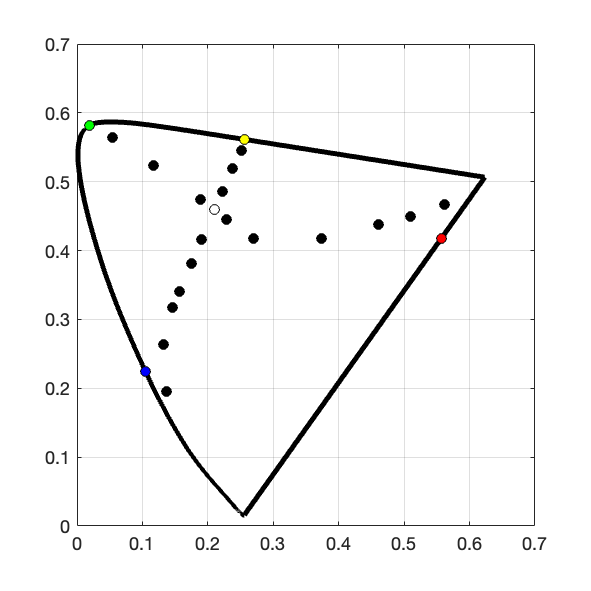

% Derive achromatic point in u'v' space

achromatic_uv = xytouv(achromatic_xy);

% Derive unique red in u'v' space

red_uv = xytouv(red_xy);

% Plot unique hue loci in u'v' chromaticity space

uvPlot = figure;
uvPlot.Position = [1080, 1080, 1155, 1155];

plot(CIEuv(:,1), CIEuv(:,2), '-k', 'LineWidth', 5);
grid on
hold on
ylim([0,0.7])
xlim([0,0.7])
plot([CIEuv(1,1), CIEuv(end,1)], [CIEuv(1,2), CIEuv(end,2)], '-k', 'LineWidth', 5);
plot(achromatic_uv(1), achromatic_uv(2), 'Marker', 'o', 'MarkerFaceColor', 'w', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
plot(CIEuv(WL_01==uniqueBlue,1), CIEuv(WL_01==uniqueBlue,2), 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
plot(CIEuv(WL_01==uniqueYellow,1), CIEuv(WL_01==uniqueYellow,2), 'Marker', 'o', 'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
plot(CIEuv(WL_01==uniqueGreen, 1), CIEuv(WL_01==uniqueGreen, 2), 'Marker', 'o', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
plot(red_uv(1), red_uv(2), 'Marker', 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)

for i = 1:length(longWavelengths)
    adaptationRatios = LMSRatios(WL_01==shortWavelength,:)+LMSRatios(WL_01==longWavelengths(i),:);
    adaptationRatios = (adaptationRatios./min(adaptationRatios)).*LMWeberFraction;
    adaptationRatios(adaptationRatios<1) = 1;
    L_adaptation = 1./adaptationRatios(1);
    M_adaptation = 1./adaptationRatios(2);
    S_adaptation = 1./adaptationRatios(3);
    L_adapted = l_cone_01.*L_adaptation;
    M_adapted = m_cone_01.*M_adaptation;
    S_adapted = s_cone_01.*S_adaptation;
    surround_adapted = percent_L.*L_adapted+percent_M.*M_adapted;
    LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
    MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
    SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);
    BY_adapted = SvsLM_adapted - LvsM_adapted;
    RG_adapted = SvsLM_adapted - MvsL_adapted;
    nullPoint = lsqnonlin(@(x) BY_adapted(WL_01==shortWavelength).*x(1)-abs(BY_adapted(WL_01==longWavelengths(i))).*x(2), x0, [], [], options);
    point_XYZ = CIEtristimulus_01(WL_01==shortWavelength,:).*nullPoint(1)+CIEtristimulus_01(WL_01==longWavelengths(i),:).*nullPoint(2);
    point_xy = [point_XYZ(1)./sum(point_XYZ), point_XYZ(2)./sum(point_XYZ)];
    point_uv = xytouv(point_xy);
    plot(point_uv(1), point_uv(2), 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
end

for i = 1:length(desaturationSeries)
    adaptationRatios = LMSRatios(WL_01==adaptationWavelengths(i),:)+LMSRatios(WL_01==uniqueYellow,:).*desaturationSeries(i);
    adaptationRatios = (adaptationRatios./min(adaptationRatios)).*LMWeberFraction;
    adaptationRatios(adaptationRatios<1)=1;
    L_adaptation = 1./adaptationRatios(1);
    M_adaptation = 1./adaptationRatios(2);
    S_adaptation = 1./adaptationRatios(3);
    L_adapted = l_cone_01.*L_adaptation;
    M_adapted = m_cone_01.*M_adaptation;
    S_adapted = s_cone_01.*S_adaptation;
    surround_adapted = percent_L.*L_adapted+percent_M.*M_adapted;
    LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
    MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
    SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);
    BY_adapted = SvsLM_adapted - LvsM_adapted;
    RG_adapted = SvsLM_adapted - MvsL_adapted;
    blue_adapted = WL_01(RG_adapted > 0-threshold & RG_adapted < 0+threshold);
    blue_adapted = blue_adapted(1);
    point_XYZ = CIEtristimulus_01(WL_01==blue_adapted,:)+(CIEtristimulus_01(WL_01==uniqueYellow,:).*desaturationSeries(i));
    point_xy = [point_XYZ(1)./sum(point_XYZ), point_XYZ(2)./sum(point_XYZ)];
    point_uv = xytouv(point_xy);
    plot(point_uv(1), point_uv(2), 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 10)
end

hold off

uvPlot.CurrentAxes.FontSize = 18;